Синусоидальный алгоритм

t = linspace(0,10,1000);
T = 4;
f = 2*pi/T;

phi1 = deg2rad(17)

phi1 = 0.2967


U = ((f^2)*phi1) / (f*T - sin(f*T))

U = 0.1165

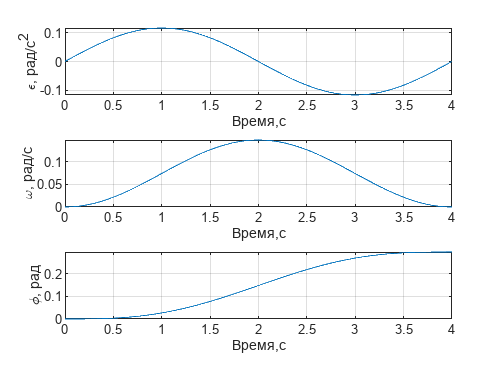



eps = U *  sin(f*t);
omeg = U/f*(1-cos(f*t));
phi = (U/f^2)*(f*t-sin(f*t));



figure('Units','normalized', 'Position',[0.1 0.1 0.6 0.8])
subplot(3,1,1);
plot(t, eps);
grid on
xlabel('Время,с');
ylabel("\epsilon, рад/с^2")
xlim([0 4])

subplot(3,1,2)
plot(t, omeg);
grid on
xlabel('Время,с');
ylabel("\omega, рад/с")
xlim([0 4])

subplot(3,1,3)
plot(t, phi);
xlabel('Время,с');
ylabel("\phi, рад")
grid on
xlim([0 4])
exportgraphics(gcf, 'sin_profile.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

figure
J = 2.96;
M = J*eps;

M =          0    0.0054    0.0108    0.0163    0.0217    0.0271    0.0325    0.0379    0.0433    0.0486    0.0540    0.0594    0.0647    0.0700    0.0753    0.0806    0.0859    0.0911    0.0963    0.1015    0.1067    0.1118    0.1169    0.1220    0.1271    0.1321    0.1371    0.1421    0.1470    0.1519    0.1567    0.1615    0.1663    0.1710    0.1757    0.1804    0.1850    0.1895    0.1940    0.1985    0.2029    0.2073    0.2116    0.2158    0.2200    0.2242    0.2283    0.2323    0.2363    0.2402



plot(t, M)
xlim([0 4])
grid on
xlabel("Время,с")
ylabel("Н \cdot м")

MaxM = max(M)

MaxM = 0.3449

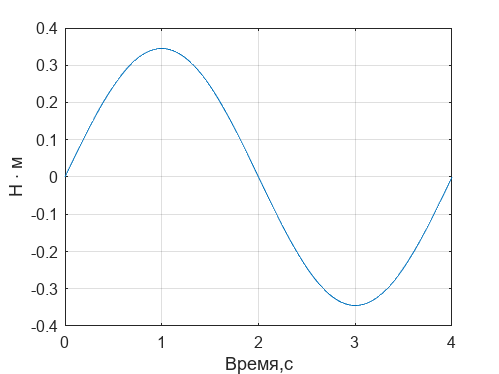


exportgraphics(gcf, 'sin_moment.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

Линейный алгоритм

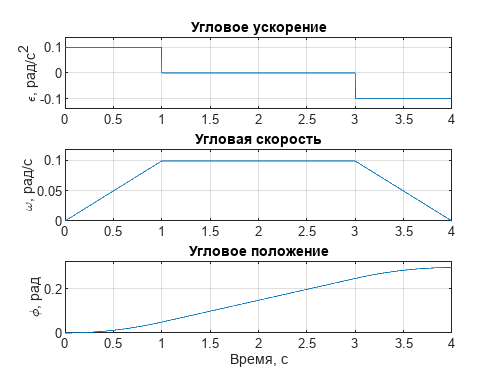

clear
clc
% Параметры
phi_total_deg = 17;                      % полный угол в градусах
phi_total = deg2rad(phi_total_deg);     % перевод в радианы
T = 4;                                   % общее время
t1 = 1; t2 = 2; t3 = 1;                  % интервалы разгона, плато, торможения

omega_max = phi_total / 3;              % максимальная угловая скорость (см. вывод ранее)
eps_val = omega_max / t1;               % постоянное угловое ускорение

% Временная ось
t = linspace(0, 4, 1000);

% Выделение интервалов
omega = zeros(size(t));
phi = zeros(size(t));
eps = zeros(size(t));

for i = 1:length(t)
    ti = t(i);
    if ti <= t1
        % Разгон
        omega(i) = eps_val * ti;
        phi(i) = 0.5 * eps_val * ti^2;
        eps(i) = eps_val;
    elseif ti <= t1 + t2
        % Плато
        omega(i) = omega_max;
        phi(i) = 0.5 * omega_max * t1 + omega_max * (ti - t1);
        eps(i) = 0;
    else
        % Торможение
        dt = ti - (t1 + t2);
        omega(i) = omega_max - eps_val * dt;
        phi(i) = 0.5 * omega_max * t1 + omega_max * t2 + omega_max * dt - 0.5 * eps_val * dt^2;
        eps(i) = -eps_val;
    end
end

% Построение графиков
figure('Units','normalized','Position',[0.1 0.5 0.6 0.8]);

subplot(3,1,1);
plot(t, eps);
grid on;
ylabel('\epsilon, рад/с^2');
xlim([0 4]);
ylim([min(eps)*1.4 max(eps)*1.4])
title('Угловое ускорение');

subplot(3,1,2);
plot(t, omega);
grid on;
ylabel('\omega, рад/с');
xlim([0 4]);
ylim([0 max(omega) * 1.2])
title('Угловая скорость');

subplot(3,1,3);
plot(t, phi);
grid on;
xlabel('Время, с');
ylabel('\phi, рад');
xlim([0 4]);
ylim([0 max(phi)*1.1])
title('Угловое положение');

% Сохранить график
exportgraphics(gcf, 'line_profile.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');